syms t;

max_time = 30;
iterations = 100;

u = t  / (max_time / 3.2);

neato_max_speed = 0.3;
neato_min_speed = -0.3;
wheel_dist = 0.245;

rr_x = 0.3960 * cos(2.65 * (u + 1.4));
rr_y = -0.99 * sin(u + 1.4);

t_vals = linspace(0, max_time, iterations);

x_vals = double(subs(rr_x, t_vals));
y_vals = double(subs(rr_y, t_vals));

plot(y_vals, x_vals)
axis equal

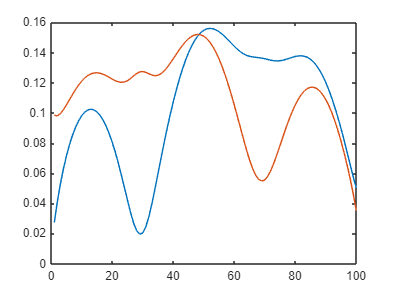


rr_vel_x = diff(rr_x);
rr_vel_y = diff(rr_y);

rr_speed = norm([rr_vel_x, rr_vel_y]);

rr_tang_x = rr_vel_x / rr_speed;
rr_tang_y = rr_vel_y / rr_speed;

rr_q_x = diff(rr_tang_x);
rr_q_y = diff(rr_tang_y);

rr_ang_vel = rr_tang_x * rr_q_y - rr_tang_y * rr_q_x;

rr_vel_left = rr_speed - (wheel_dist / 2) * rr_ang_vel;
rr_vel_right = rr_speed + (wheel_dist / 2) * rr_ang_vel;

plot(double(subs(rr_vel_left, t, t_vals)));
hold on;
plot(double(subs(rr_vel_right, t, t_vals)));
hold off

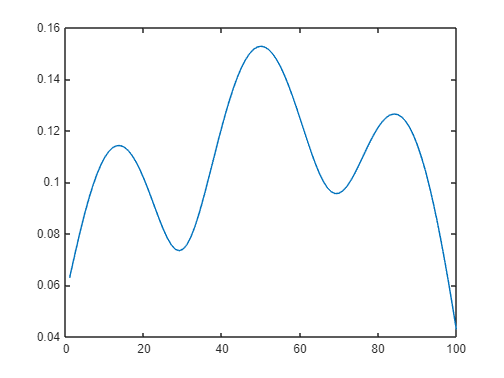

plot(double(subs(rr_speed, t_vals)))


vel_left = double(subs(rr_vel_left, t, t_vals));
vel_right = double(subs(rr_vel_right, t, t_vals));
%return

ip = "192.168.16.176"; name = "confirmed";

neatov3.connect(ip)

Deleting previous Neato connection.
Connecting to the Neato.


Testing connection.
Connection successful.


ans =   neatov3 with no properties.


count = 1;
tic;

t_range = 0:0.2:40

t_range =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000



vel_left_range = double(subs(rr_vel_left, t, t_range))

vel_left_range =     0.0273    0.0368    0.0452    0.0528    0.0596    0.0658    0.0714    0.0764    0.0810    0.0850    0.0887    0.0918    0.0946    0.0969    0.0989    0.1004    0.1015    0.1022    0.1024    0.1023    0.1018    0.1009    0.0996    0.0979    0.0958    0.0933    0.0904    0.0872    0.0836    0.0796    0.0753    0.0706    0.0657    0.0605    0.0551    0.0495    0.0440    0.0385    0.0333    0.0286    0.0246    0.0217    0.0199    0.0195    0.0205    0.0229    0.0265    0.0313    0.0368    0.0430


vel_right_range = double(subs(rr_vel_right, t, t_range))

vel_right_range =     0.0984    0.0979    0.0984    0.0995    0.1012    0.1031    0.1053    0.1076    0.1099    0.1122    0.1144    0.1164    0.1184    0.1201    0.1217    0.1231    0.1242    0.1251    0.1258    0.1263    0.1266    0.1266    0.1265    0.1262    0.1258    0.1252    0.1245    0.1238    0.1230    0.1223    0.1216    0.1210    0.1206    0.1203    0.1203    0.1206    0.1212    0.1220    0.1230    0.1241    0.1252    0.1263    0.1270    0.1274    0.1275    0.1272    0.1266    0.1260    0.1254    0.1249



while toc <= 1
    neatov3.setVelocities(interp1(t_vals, vel_left, 0), interp1(t_vals, vel_right, 0))
end

tic;

while toc <= iterations
    %if(toc >= max_time / iterations)
    %    count = count + 1;
    %    tic
    %end
    %neatov3.setVelocities(interp1(t_range, vel_left_range, toc), interp1(t_range, vel_right_range, toc))
    neatov3.setVelocities(interp1(t_vals, vel_left, toc), interp1(t_vals, vel_right, toc))
    sensors = neatov3.receive();
    if length(sensors.encoders) >= 2
        left_encoder = sensors.encoders(1);
        right_encoder = sensors.encoders(2);
    end

end


neatov3.disconnect()